# Create Live Editor Task from Selection

If you have code in the Live Editor that contains controls such as numeric sliders, numeric spinners, buttons, or drop-down lists, you can convert that code into your own Live Editor task. Creating tasks from a code selection simplifies the task creation process, making it easier to create tasks that you can then reuse throughout your code and share with others.

## Create Task

To create your own Live Editor task from a code selection, after selecting the code, go to the **Live Editor** tab, and in the **Code** section, select **Task** > **Convert to Task**. When prompted, enter a name for the task, the name of the task class definition file to create, an optional description of the task, and some optional keywords. MATLAB® creates your Live Editor task from the selection and adds the task to the Live Editor task gallery. Supported controls include numeric sliders, numeric spinners, drop-down lists, check boxes, edit fields, buttons, and file browsers.

For example, this live script contains code for creating a fractal tree and includes two numeric sliders.

tree = @(c,x,r) cumsum(exp(1i*(c*x.*x + r)));
c = pi*(1+sqrt(5))/2;

npts = 68 * 100;
x = 0:npts;
r = 3;
z = tree(c,x,r);

plot(real(z),imag(z),".");
axis equal
axis on
axis ([-20 80 -20 80])

To create a Live Editor task from the fractal tree creation code, select it and then go to the **Live Editor** tab, and in the **Code** section, select **Task**** > Convert to Task**. In the Convert to Task dialog box that opens, enter a name for the task, the name of the task class definition file to create, an optional description of the task, and some optional keywords. 

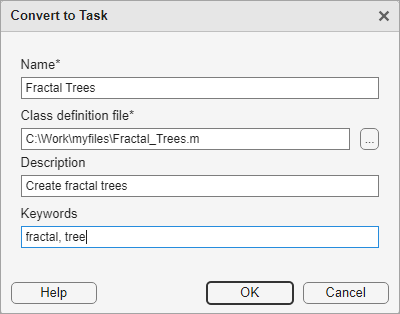

Click **OK** to create the Live Editor task. MATLAB creates two files:

- A task class definition file containing the code for the task

- A JSON file containing the metadata needed to display the task in the Live Editor task gallery and in automatic code suggestions and completions 

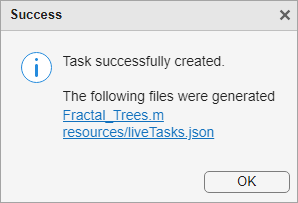

MATLAB also creates a sample live script containing the Live Editor task to show what the newly created task looks like.

## Add Task to Live Script

To add your task to a live script, in the live script, type one of the keywords defined in the Convert to Task dialog box and select your task from the list of suggested names.

For example, to add the Fractal Trees task to a live script, on a code line, type `fractal`. MATLAB shows a list of suggested matches. 

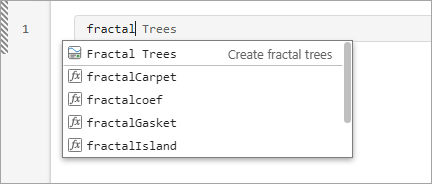

Select **Fractal Trees** from the list. MATLAB adds the Fractal Trees task to the live script.

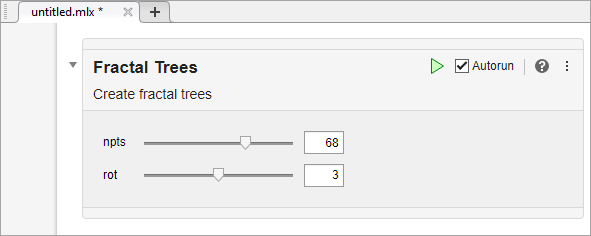

To add your task from the toolstrip, go to the **Live Editor** tab and in the **Code** section, click **Task**. Select `Fractal Trees` to add the Fractal Trees task to your live script.

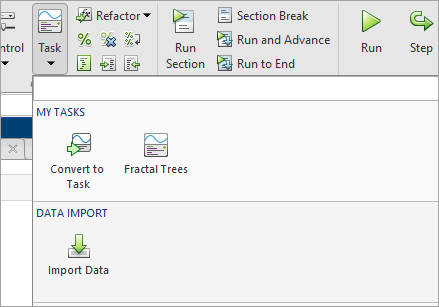

## Modify Your Task

After creating a Live Editor task from a code selection, you can modify the task user interface, generated code, and other task features by updating the task class definition file and metadata. For more information, see [Live Editor Task Development Overview](docid:creating_guis#mw_7c98c41d-8ab2-4aa3-8af6-380a3d280f47).

*Copyright 2023 The MathWorks, Inc.*